#  =============================================

# Problem 1: Basic Plant Response Analysis

# =============================================

###  Open-loop Analysis:

-  Plot the step response of the open-loop system

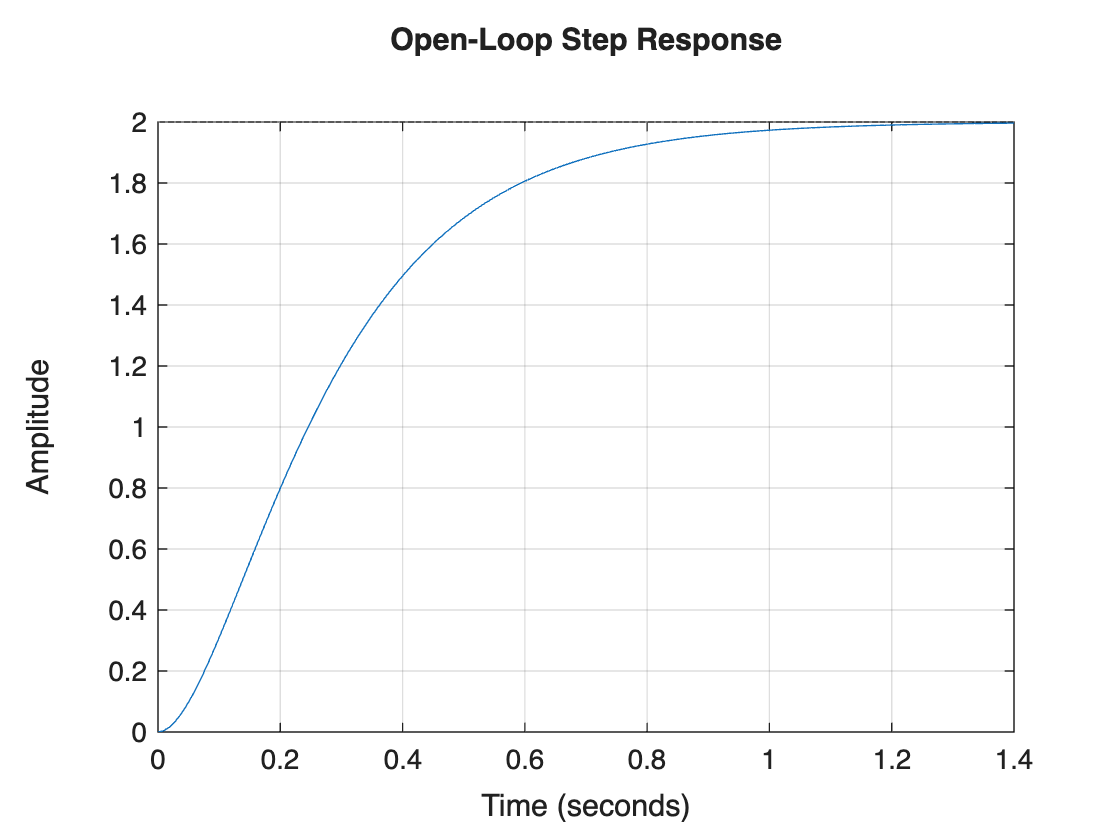

% Define plant G(s) = 100 / (s^2 + 15s + 50)
num = 100;
den = [1 15 50];
G = tf(num, den);

figure;
step(G);
grid on;
title('Open-Loop Step Response');

Calculate and report: rise time, settling time, peak overshoot, and steady-state error

% Performance metrics
info_ol = stepinfo(G);
fprintf('Open-loop Rise Time: %.3f s\n', info_ol.RiseTime);

Open-loop Rise Time: 0.518 s


fprintf('Open-loop Settling Time: %.3f s\n', info_ol.SettlingTime);

Open-loop Settling Time: 0.920 s


fprintf('Open-loop Overshoot: %.2f %%n', info_ol.Overshoot);

Open-loop Overshoot: 0.00 %n

fprintf ('Open-loop Peak : %.3f\n', info_ol.Peak);

Open-loop Peak : 1.998


SP = 1;
[y, ~] = step(SP * G);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Steady State Error: %.3f\n', steady_state_error);

Steady State Error: 0.993


Proportional controller with Kp = 0.5

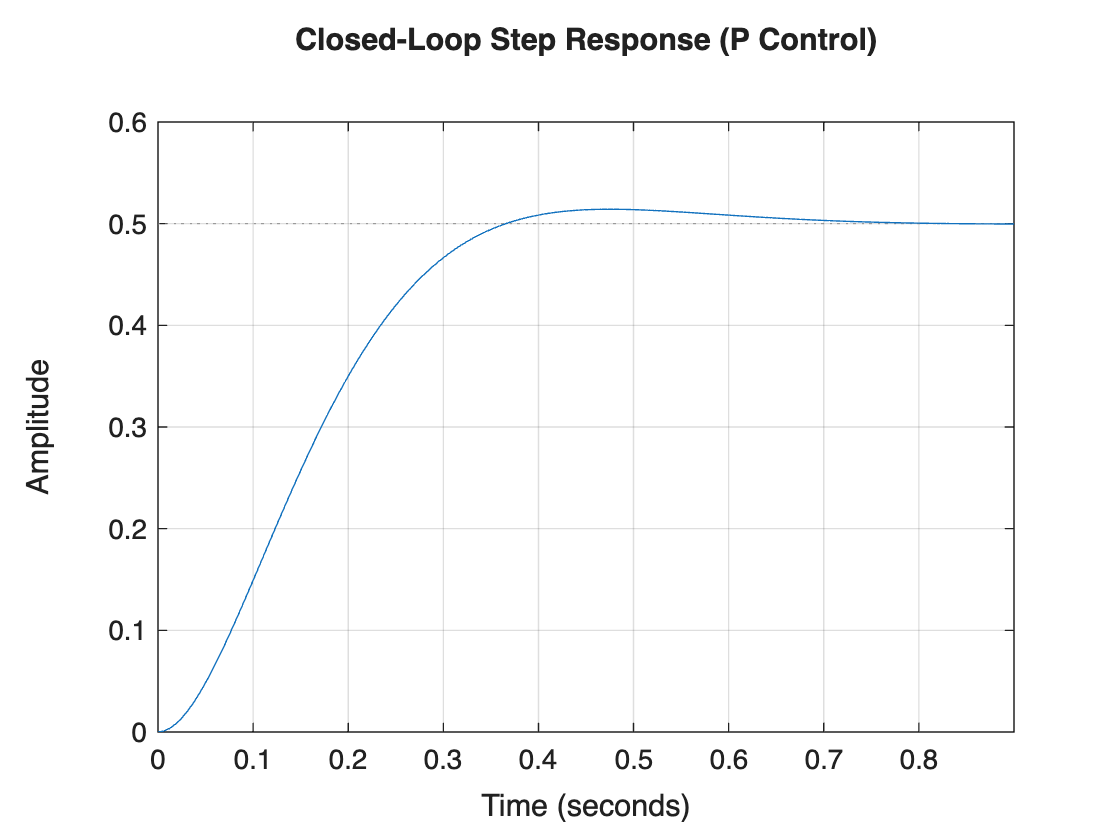

Kp = 0.5;
C_P = tf(Kp, 1);
sys_P = feedback(C_P * G, 1);

figure;
step(sys_P);
grid on;
title('Closed-Loop Step Response (P Control)');


info_P = stepinfo(sys_P);
disp(info_P);

         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728



With proportional control, the control signal is proportional to the current error. As the error decreases, the control effort decrease as well. At steady state, a non-zero error is required to generate enough control action. Therefore, proportional control alone cannot eliminate steady-state error.

## 1(c) PI Controller (Kp = 0.5, Ki = 1.5)

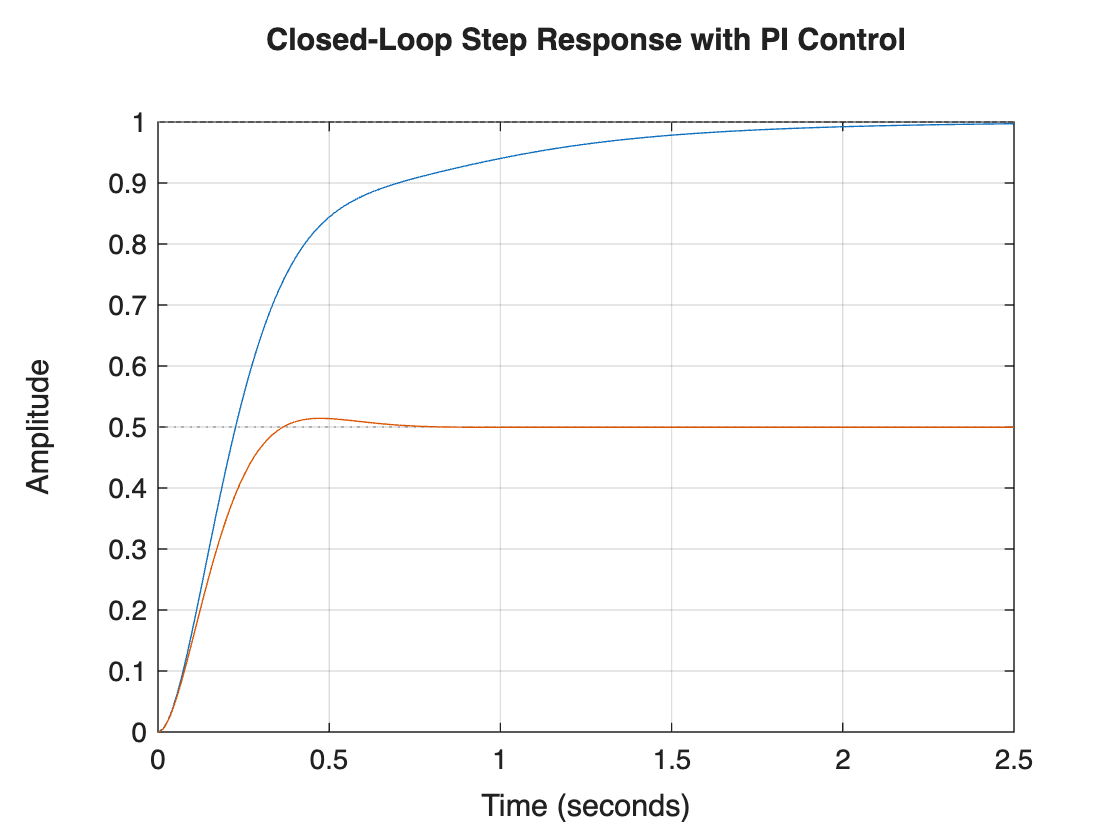

Ki = 1.5;
C_PI = pid(Kp, Ki, 0);
sys_PI = feedback(C_PI * G, 1);

figure;
step(sys_PI, sys_P);
grid on;
title('Closed-Loop Step Response with PI Control');


info_PI = stepinfo(sys_PI);
disp(info_PI);

         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861




SP = 1; 
[y, ~] = step(SP * sys_PI);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Closed-Loop Steady State Error: %.3f\n', steady_state_error);

Closed-Loop Steady State Error: 0.004


The integral term accumulates the error over time. If a steady-state error exists, the integral term continues to increase, which increases the control input until the error is driven to zero. As a result, the PI controller eliminates steady-state error that remains when using only proportional control.

##  PID Controller (Tuned)

%pidTuner(G,'PID');

Kp = 0.9931;
Ki = 4.8444;
Kd = 0.044209;
C_PID = pid(Kp, Ki, Kd); %Kp, Ki, Kd found at bottom right corner
disp(Kp);

    0.9931



disp(Ki);

    4.8444



disp(Kd);

    0.0442



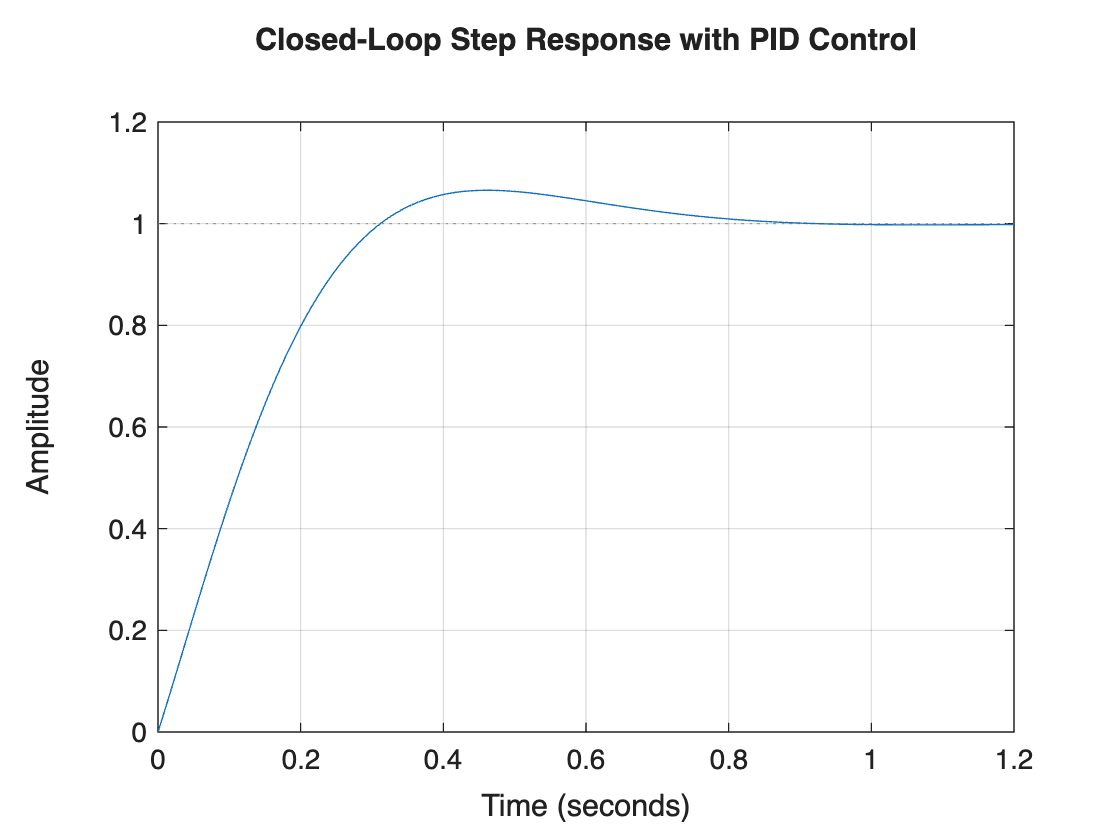

sys_PID = feedback(C_PID * G, 1);
figure;
step(sys_PID);

grid on;
title('Closed-Loop Step Response with PID Control');


info_PID = stepinfo(sys_PID);
disp(info_PID);

         RiseTime: 0.2225
    TransientTime: 0.7237
     SettlingTime: 0.7237
      SettlingMin: 0.9053
      SettlingMax: 1.0657
        Overshoot: 6.5696
       Undershoot: 0
             Peak: 1.0657
         PeakTime: 0.4604




SP = 1;
[y, ~] = step(SP * sys_PID);
steady_state_output = y(end);
steady_state_error = abs(SP - steady_state_output);
fprintf('Steady State Error: %.3f\n', steady_state_error);

Steady State Error: 0.002


# =============================================

# Problem 2: Complex Input Tracking

# =============================================

t = (0:0.01:20)';

%% 2(a) Multi-Step Reference

r = zeros(size(t));
for i = 1:length(t)
    if t(i) < 5
        r(i) = 1;
    elseif t(i) < 10
        r(i) = 1.5;
    elseif t(i) < 15
        r(i) = 0.8;
    else
        r(i) = 1.2;
    end
end

- Simulate using lsim() and plot reference vs output

- Calculate the tracking error over time

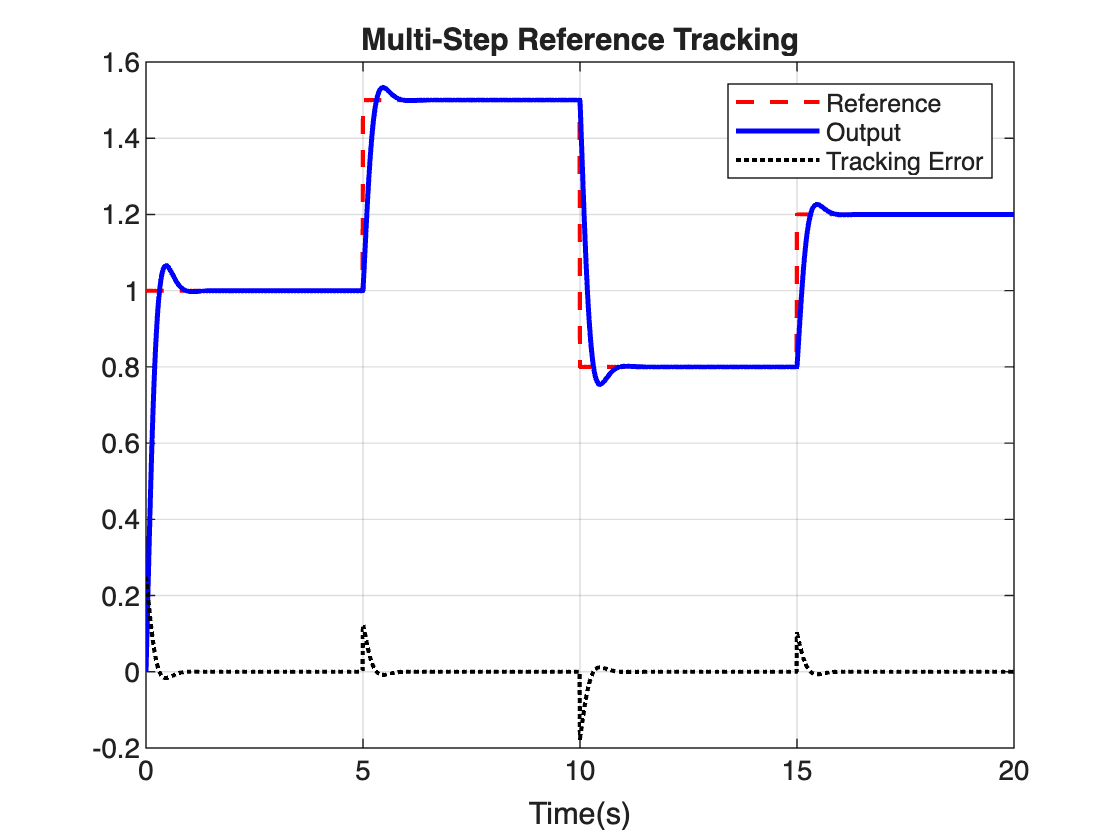

y_ms = lsim(sys_PID, r, t);
error_ms = r - y_ms;
escale =0.25; %scaling facot because the error spread was too wide.
figure;
plot(t, r, 'r--', 'LineWidth', 1.5);
hold on;
plot(t, y_ms, 'b', 'LineWidth', 1.8);
plot(t,escale*error_ms, 'k:', 'LineWidth', 1.5);
grid on;
xlabel('Time(s)');
title('Multi-Step Reference Tracking');
legend('Reference', 'Output','Tracking Error');
hold off;

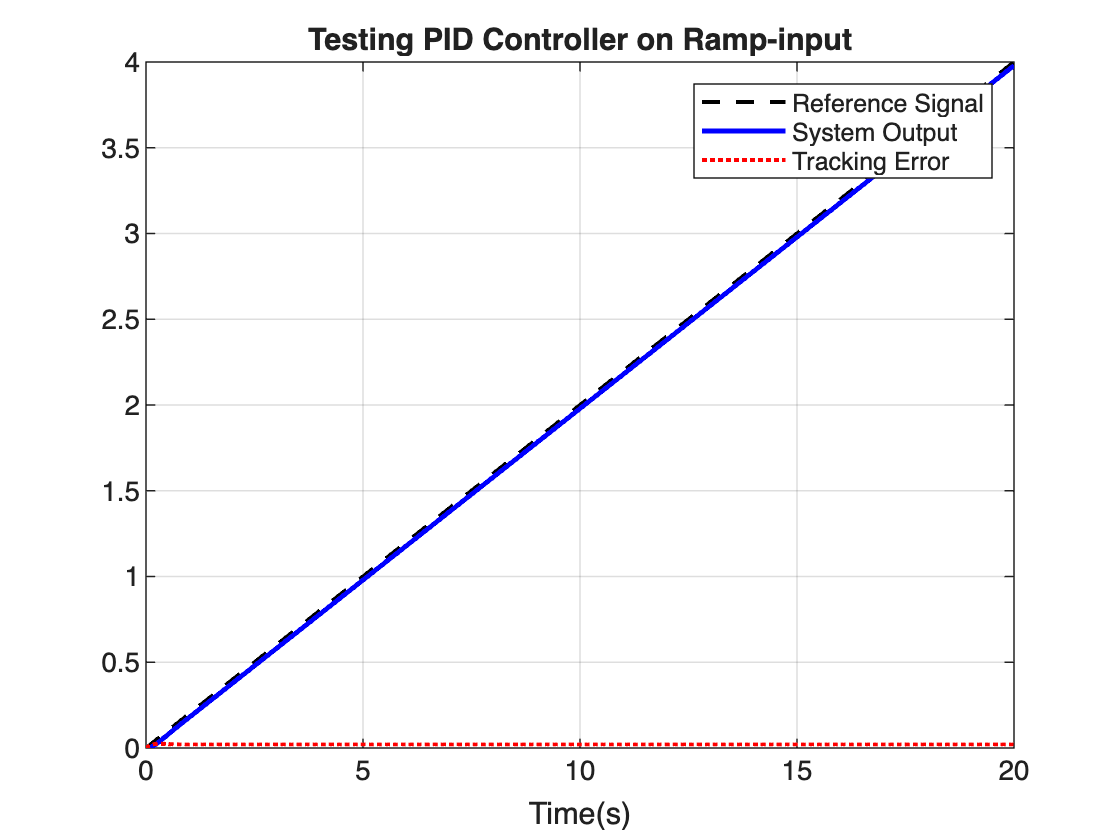

%% 2(b) Ramp Input

r_ramp = 0.2 * t;
[y_ramp, ~] = lsim(sys_PID, r_ramp, t);
error_ramp = r_ramp - y_ramp;

figure;
plot(t, r_ramp, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y_ramp, 'b', 'LineWidth', 1.8);
plot(t, error_ramp, 'r:', 'LineWidth', 1.5);
grid on;
xlabel('Time(s)');
title('Testing PID Controller on Ramp-input');
legend('Reference Signal', 'System Output', 'Tracking Error');
hold off;

A ramp input continuously increases with time, which requires a continuously increasing control effort. A standard PID controller cannot perfectly track a ramp input, resulting in a steady-state tracking error. Although the controller reduces the error, it cannot drive it completely to zero for a continuously changing reference.

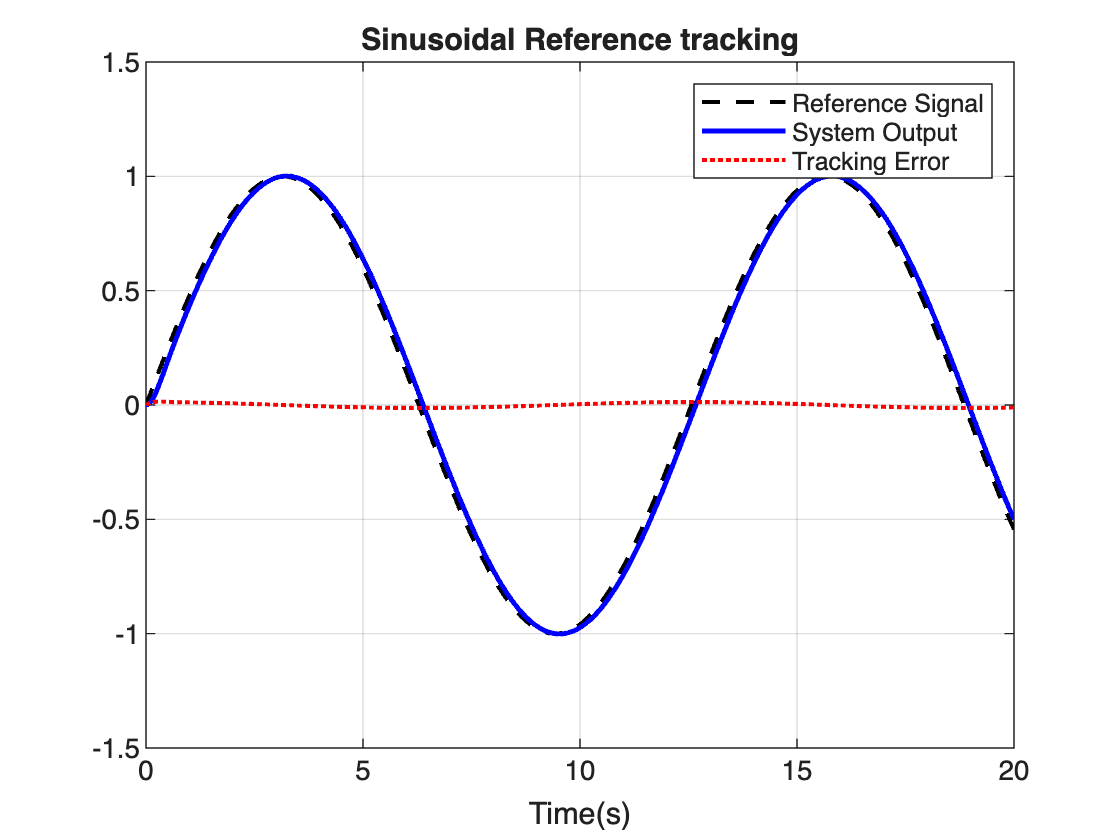

%% 2(c) Sinusoidal Reference

r = sin(0.5 * t);
y = lsim( sys_PID, r, t);
e=r-y;
figure;
plot(t, r, 'k--', 'LineWidth', 1.5);
hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
plot(t, 0.25*e, 'r:', 'LineWidth', 1.5);
grid on;
xlabel('Time(s)');
title('Sinusoidal Reference tracking');
legend('Reference Signal', 'System Output', 'Tracking Error');
hold off;

The derivative term most affects sinusoidal tracking because it improves phase response and damping. It helps the system respond more quickly to changes in the reference, reducing phase lag between the output and the sinusoidal input.

# =============================================

# Problem 3: Practical PID Implementation Challenges

# =============================================

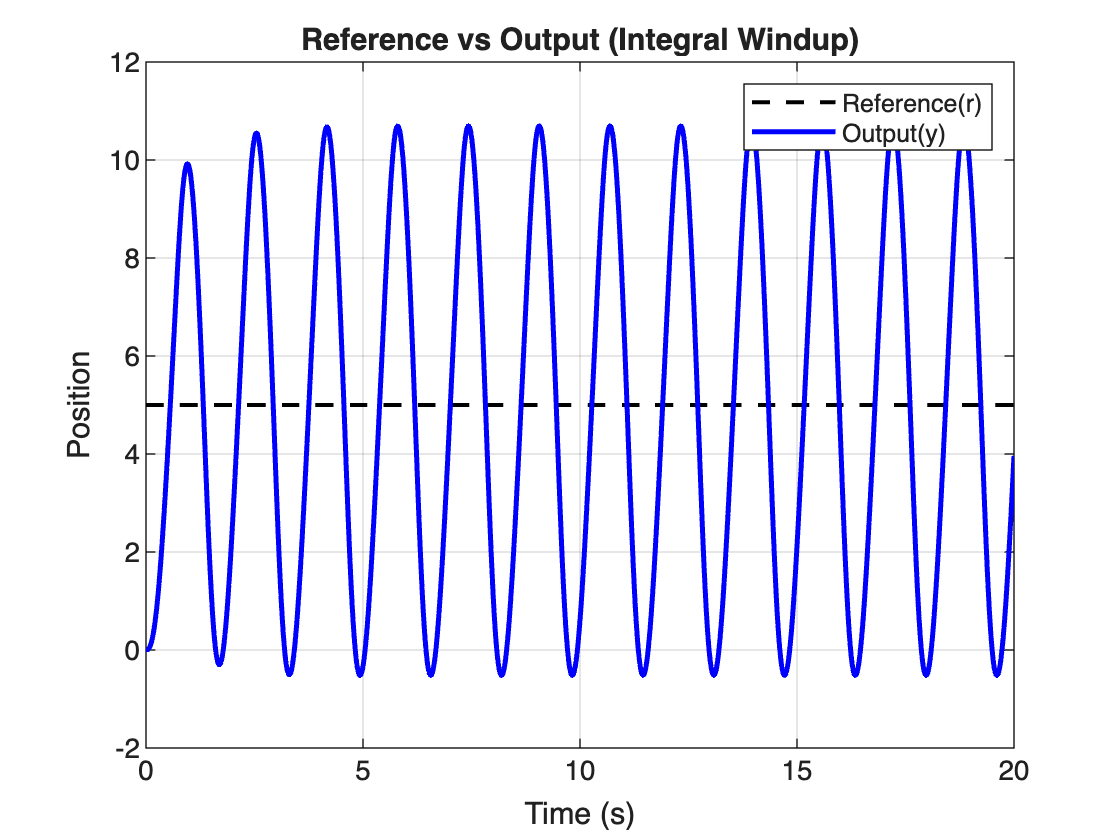

% New plant
num2 = 50;
den2 = [1 8 25 20];
G2 = tf(num2, den2);

dt = 0.01;
t = 0:dt:20;
N = length(t);
y_dot = 0;
y_ddot = 0;

y = zeros(1, N);
u = zeros(1, N);
u_sat = zeros(1, N);
r = 5 * ones(1, N);
e = zeros(1, N);
e_int = 0;
I_term = zeros(1,N);


Kp = 5;
Ki = 8;
%% 3(a) Integral Windup (No Anti-Windup)

for k = 1:N-1

    % Error
    e(k) = r(k) - y(k);

    % Integrate error (NO anti-windup)
    e_int = e_int + e(k)*dt;
    I_term(k) = Ki * e_int;

    % Unsaturated control
    u(k) = Kp*e(k) + I_term(k);

    % Actuator saturation
    u_sat(k) = max(min(u(k), 10), -10);

    % Plant differential equation (Was Calculated Manually)
    y_tdot = 50*u_sat(k) - 20*y(k) - 25*y_dot - 8*y_ddot;

    % Integrate plant states
    y_ddot = y_ddot + y_tdot*dt;
    y_dot  = y_dot  + y_ddot*dt;
    y(k+1) = y(k)   + y_dot*dt;
end
%output vs refrence
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y, 'b', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Position');
title('Reference vs Output (Integral Windup)');
legend('Reference(r)','Output(y)');

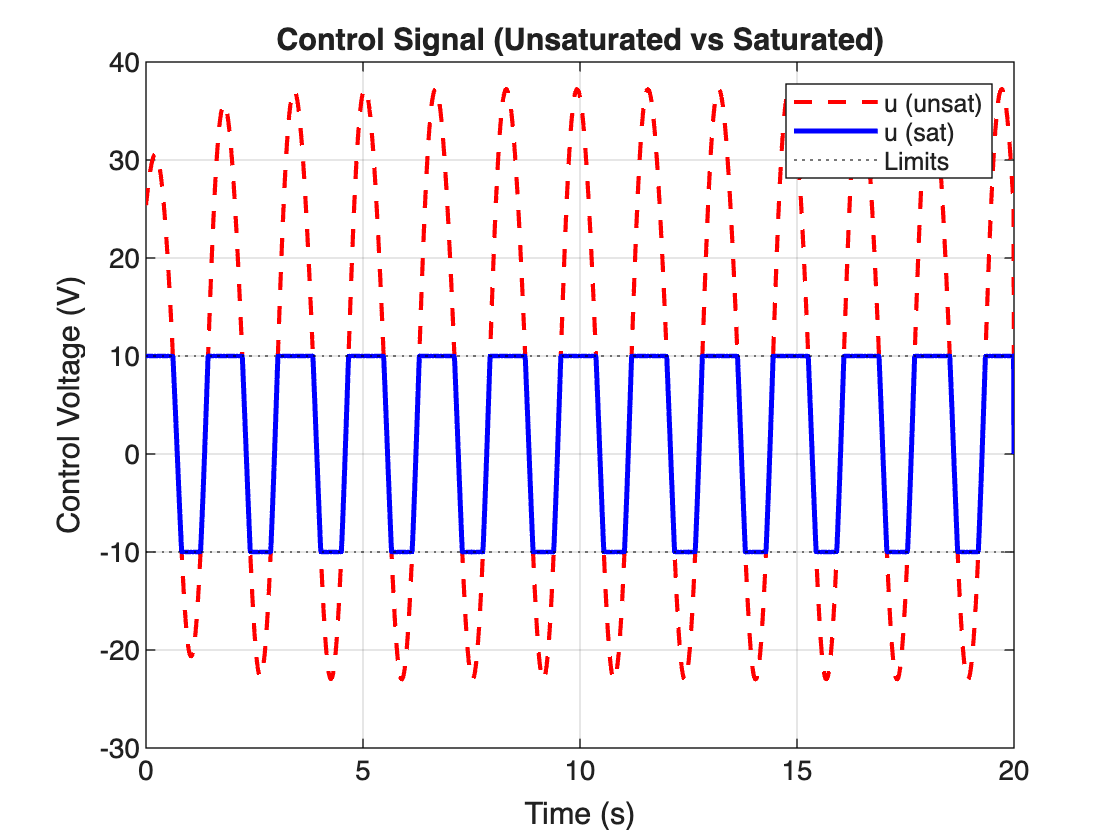

%control signals
figure;
plot(t, u, 'r--', 'LineWidth', 1.5); hold on;
plot(t, u_sat, 'b', 'LineWidth', 1.8);
yline(10,'k:'); yline(-10,'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Voltage (V)');
title('Control Signal (Unsaturated vs Saturated)');
legend('u (unsat)','u (sat)','Limits');

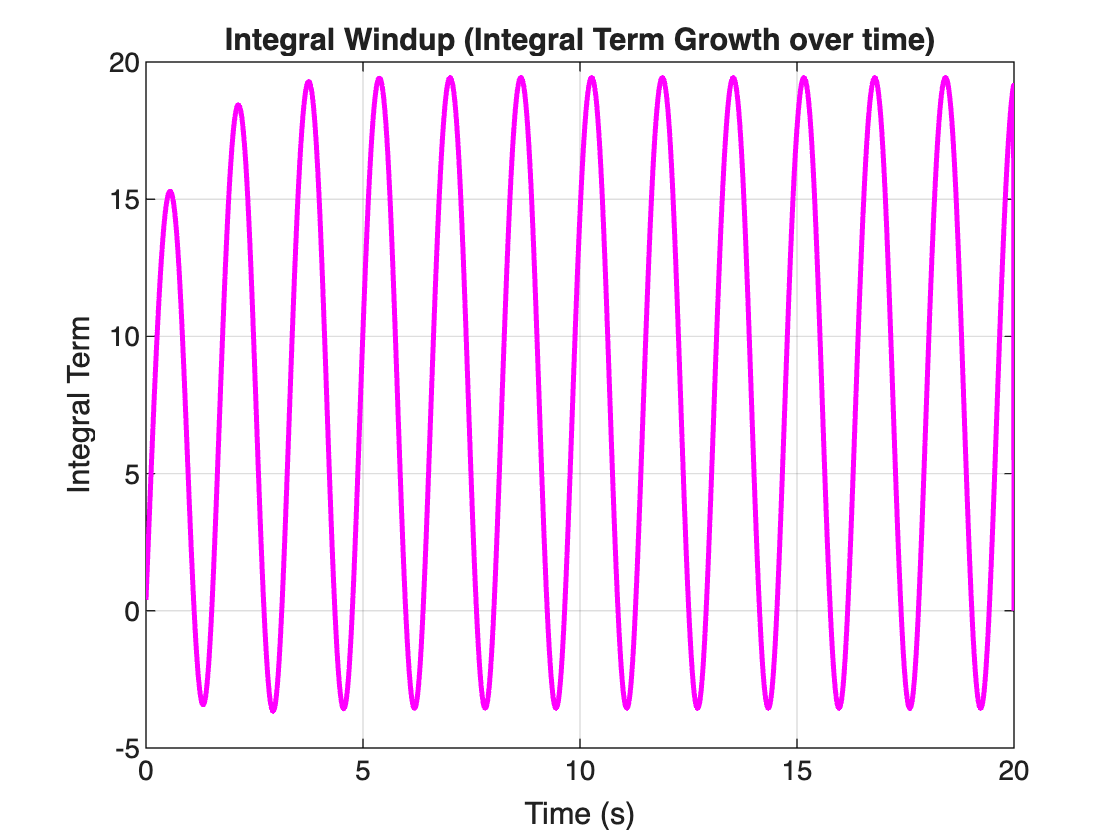


% Integral term
figure;
plot(t, I_term, 'm', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Integral Term');
title('Integral Windup (Integral Term Growth over time)');

`When does saturation occur? `

Saturation occurs when the control signal exceeds the actuator limits due to a large error. 

in this case Saturation happens at the step input. The initial error of 5 produces 

u(0) = Kp⋅5 = 25  >  10.

`What happens to the integral term during saturation?`

The integral term continues to accumulate error even though the actuator cannot apply additional control effort. 

`How does this affect overshoot and settling time when the output finally approaches setpoint?`

When the system exits saturation, the accumulated integral term causes excessive overshoot and increases the settling time.

## Anti-windup

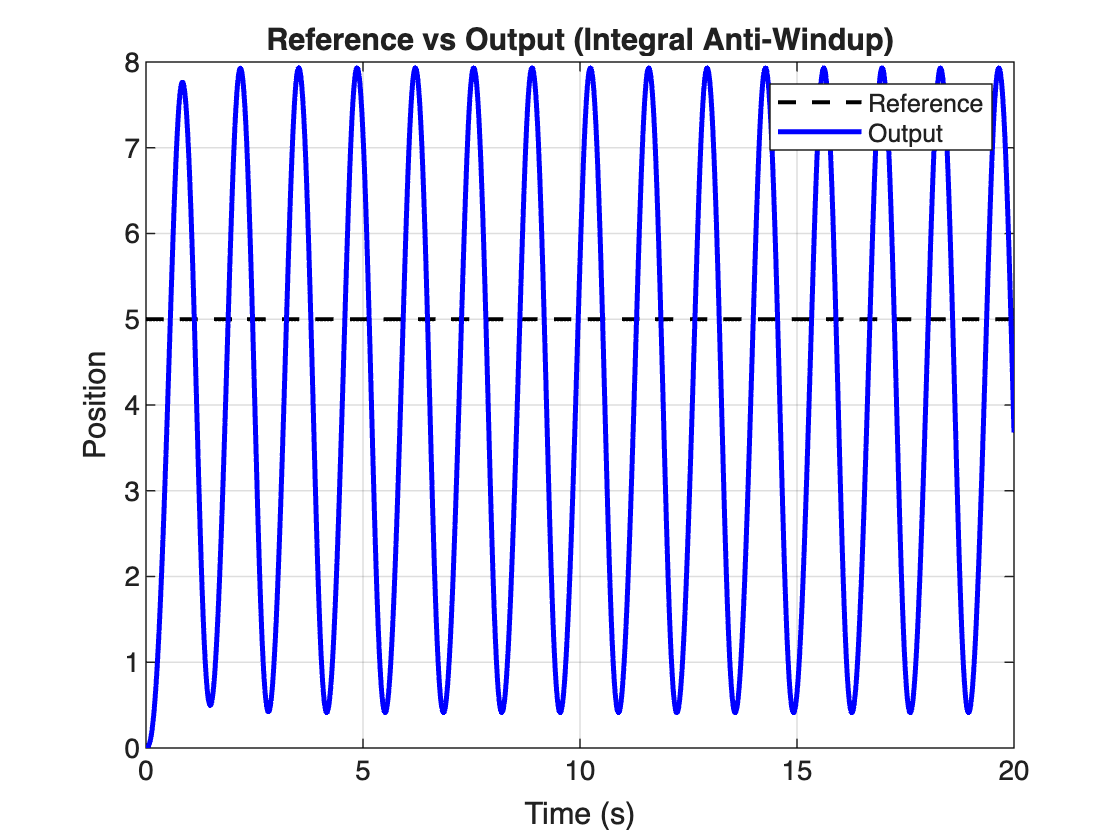


Kp = 5;
Ki = 8;
Kt = sqrt(Ki);

dt = 0.01;
t  = 0:dt:20;
N  = length(t);

r = 5 * ones(1, N); 

y1 = zeros(1,N); 
y1_dot = 0; 
y1_ddot = 0;

e1 = zeros(1,N);
u1_unsat = zeros(1,N);
u1_sat = zeros(1,N);
I1_term = zeros(1,N);

e_int1 = 0;

% Time-domain simulation

for k = 1:N-1

    % Error
    e1(k) = r(k) - y1(k);

    % Unsaturated control
    u1_unsat(k) = Kp*e1(k) + Ki*e_int1;

    % Actuator saturation
    u1_sat(k) = max(min(u1_unsat(k), 10), -10);

    % Ani-Windup back-calculation
    e_int1 = e_int1 + (e1(k) + (u1_sat(k) - u1_unsat(k))/Kt)*dt;
    I1_term(k) = Ki * e_int1;

    % Plant differential equation (Was Calculated Manually)
    y1_tdot = 50*u1_sat(k) - 20*y1(k) - 25*y1_dot - 8*y1_ddot;

    % Integrate plant states
    y1_ddot = y1_ddot + y1_tdot*dt;
    y1_dot  = y1_dot  + y1_ddot*dt;
    y1(k+1) = y1(k)   + y1_dot*dt;
end

% Plots
% Output vs reference
figure;
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y1, 'b', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Position');
title('Reference vs Output (Integral Anti-Windup)');
legend('Reference','Output');

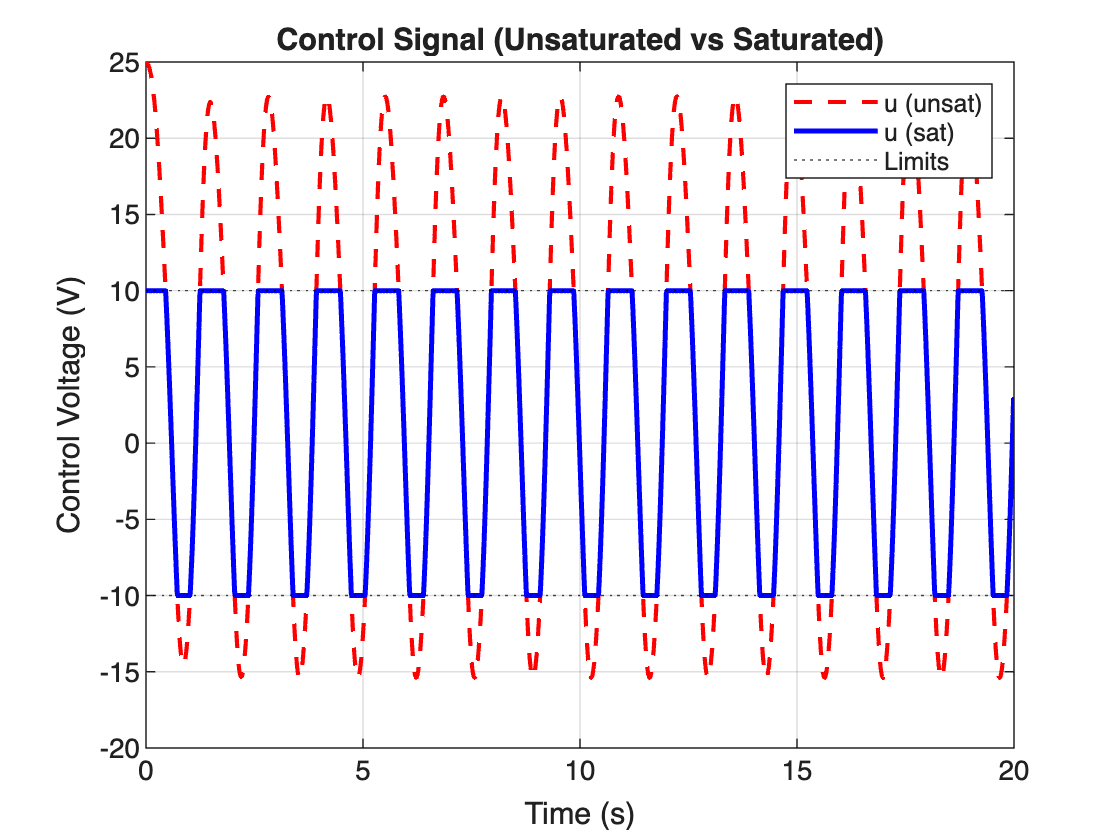

% Control signals
figure;
plot(t, u1_unsat, 'r--', 'LineWidth', 1.5); hold on;
plot(t, u1_sat, 'b', 'LineWidth', 1.8);
yline(10,'k:'); yline(-10,'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Voltage (V)');
title('Control Signal (Unsaturated vs Saturated)');
legend('u (unsat)','u (sat)','Limits');

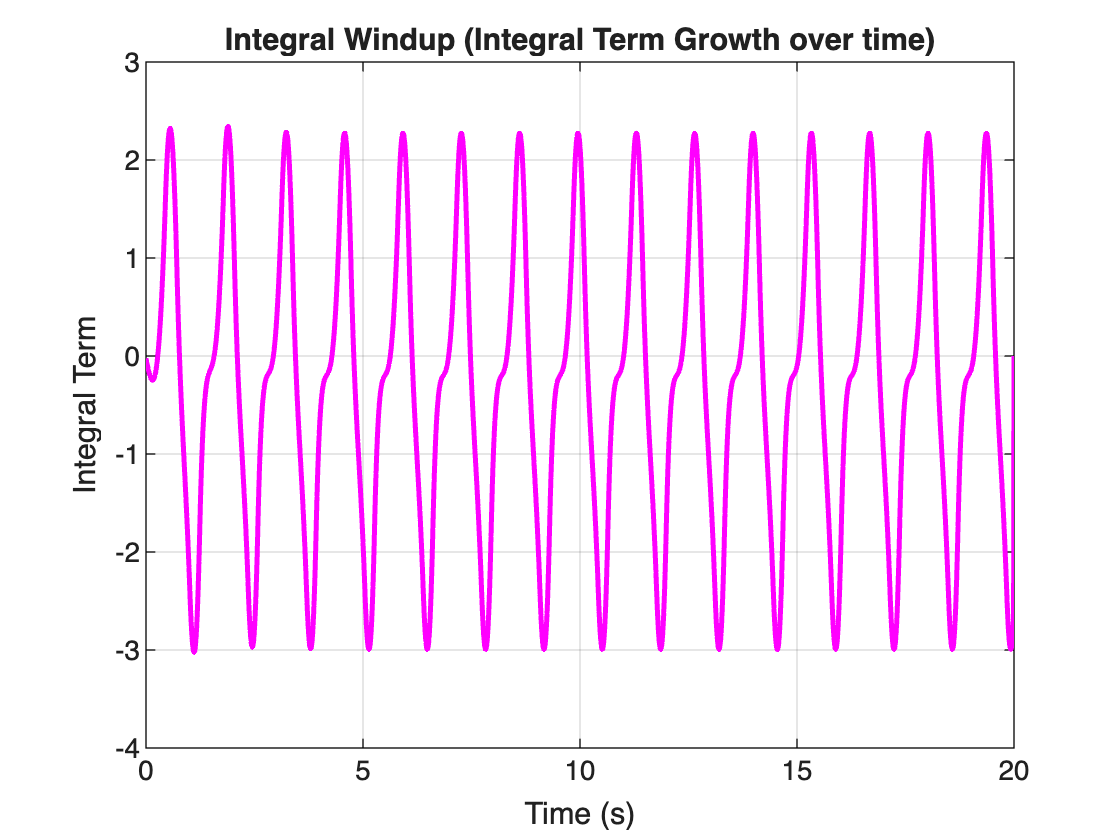

% Integral 
figure;
plot(t, I1_term, 'm', 'LineWidth', 1.8);
grid on;
xlabel('Time (s)');
ylabel('Integral Term');
title('Integral Windup (Integral Term Growth over time)');

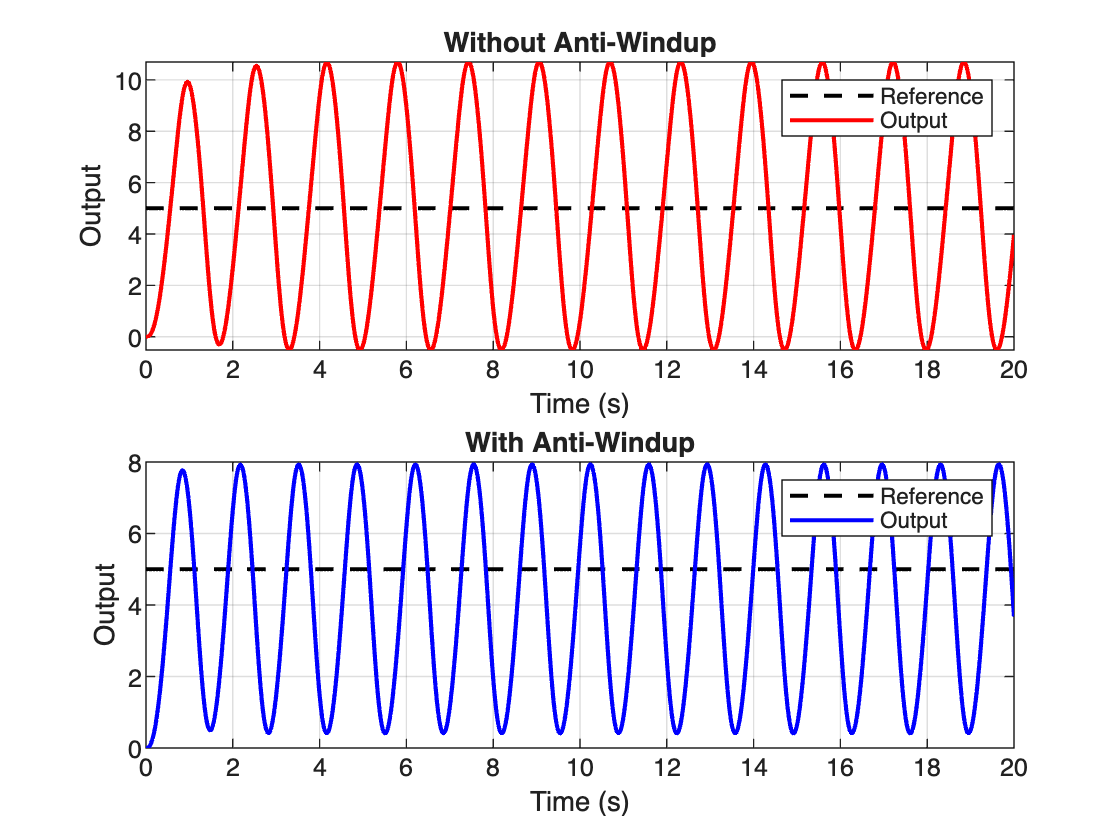

% Output response
figure;
subplot(2,1,1)
plot(t,r,'k--',t,y,'r','LineWidth',1.5)
grid on
title('Without Anti-Windup')
xlabel('Time (s)'), ylabel('Output')
legend('Reference','Output')

subplot(2,1,2)
plot(t,r,'k--',t,y1,'b','LineWidth',1.5)
grid on
title('With Anti-Windup')
xlabel('Time (s)'), ylabel('Output')
legend('Reference','Output')

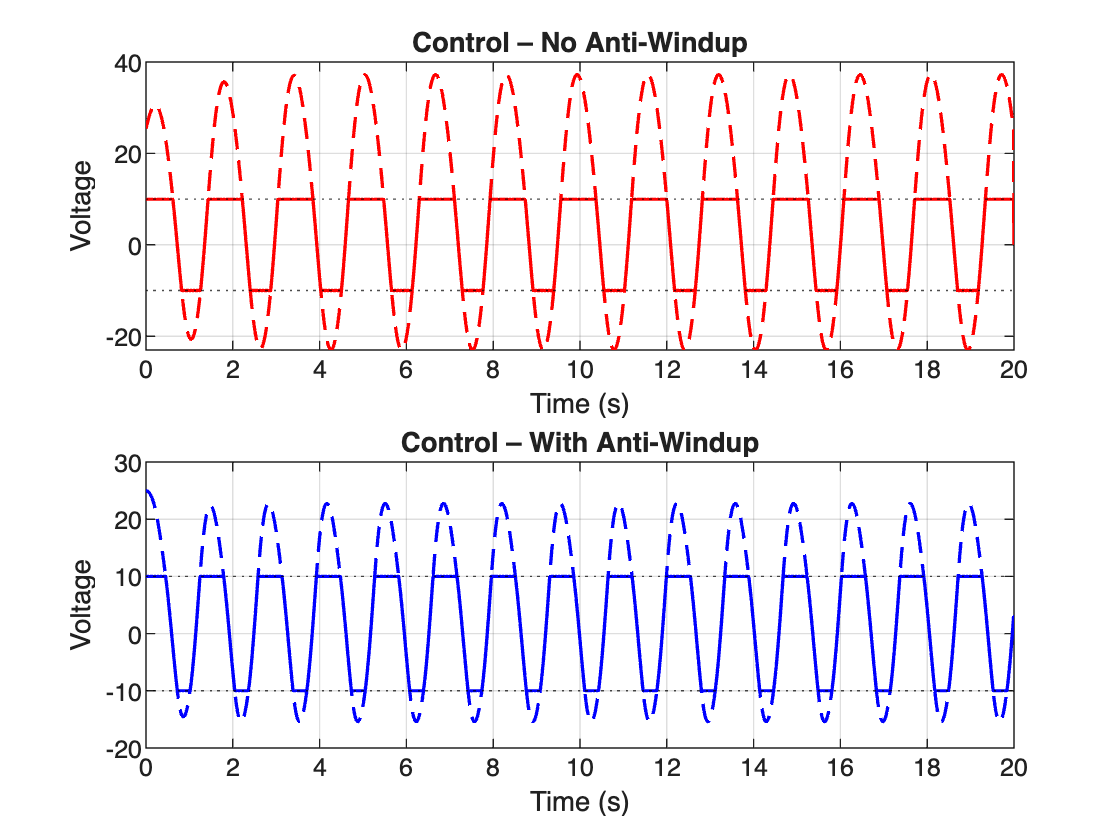


% Control Signals
figure;
subplot(2,1,1)
plot(t,u,'r--',t,u_sat,'r','LineWidth',1.2)
yline(10,'k:'), yline(-10,'k:')
grid on
title('Control – No Anti-Windup')
xlabel('Time (s)'), ylabel('Voltage')

subplot(2,1,2)
plot(t,u1_unsat,'b--',t,u1_sat,'b','LineWidth',1.2)
yline(10,'k:'), yline(-10,'k:')
grid on
title('Control – With Anti-Windup')
xlabel('Time (s)'), ylabel('Voltage')

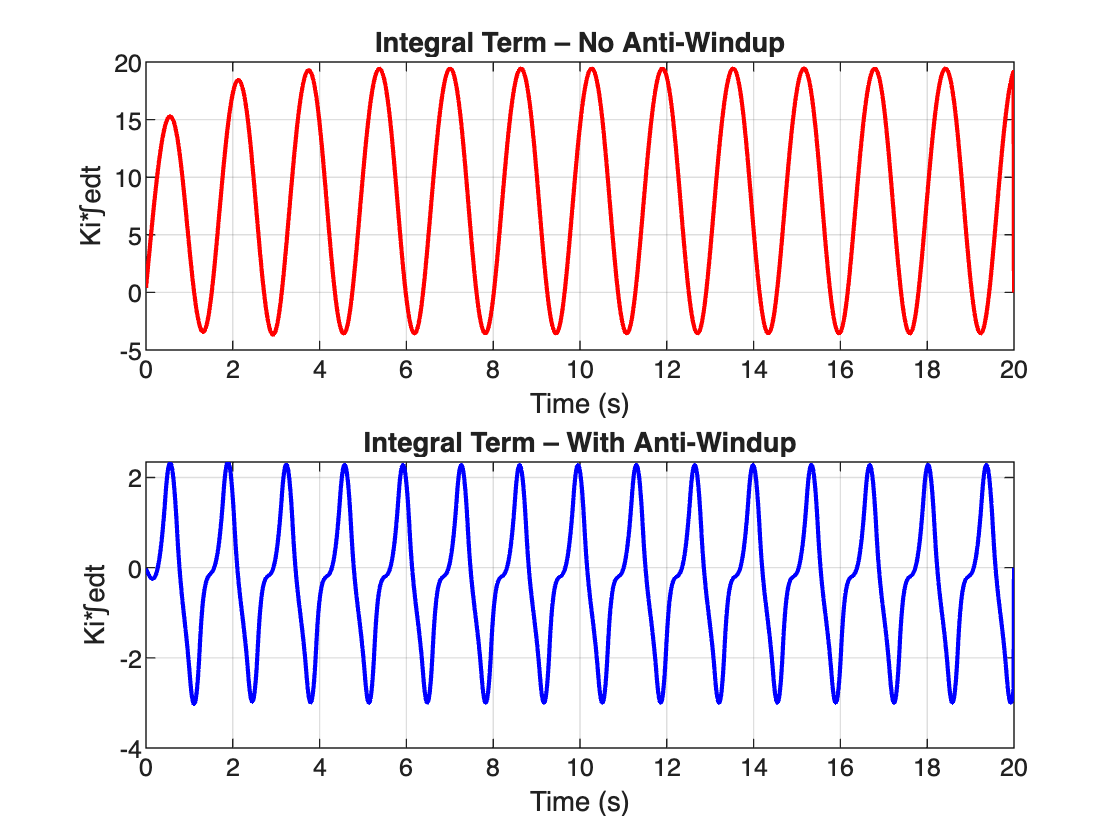


% Integral 
figure;
subplot(2,1,1)
plot(t,I_term,'r','LineWidth',1.5)
grid on
title('Integral Term – No Anti-Windup')
xlabel('Time (s)'), ylabel('Ki*∫edt')

subplot(2,1,2)
plot(t,I1_term,'b','LineWidth',1.5)
grid on
title('Integral Term – With Anti-Windup')
xlabel('Time (s)'), ylabel('Ki*∫edt')

Table creation-

% Reference and tolerance
reference = 5;
tol = 0.1;   % 2% calculation

% Max overshoot
OS_noAW = (max(y) - reference)/reference * 100; % no Anti-Windup
OS_AW   = (max(y1) - reference)/reference * 100; % Anti-Windup

% Settling time (2%)
Ts_noAW = NaN; 
Ts_AW   = NaN;

%t(k) will be the settling time

for k = 1:N-1
    if all(abs(y(k:end) - reference) <= 0.1)
        Ts_noAW = t(k); 
        break
    end
end

for k = 1:N-1
    if all(abs(y1(k:end) - reference) <= 0.1)
        Ts_AW = t(k); 
        break
    end
end

% Time spent in saturation
Tsat_noAW = sum(abs(u_sat) >= 9.999) * dt; %no anti-windup
Tsat_AW   = sum(abs(u1_sat) >= 9.999) * dt; %anti-windup

% Create table
PT = table( [OS_noAW; OS_AW], [Ts_noAW; Ts_AW], [Tsat_noAW; Tsat_AW], ...
    'VariableNames', {'Max Overshoot percent','Settling Time s','Time In Saturation_s'}, ...
    'RowNames', {'Without Anti-Windup','With Anti-Windup'} );

disp(PT)

                           Max_Overshoot_percent    Settling_Time_s    Time_In_Saturation_s
                           _____________________    _______________    ____________________

    Without_Anti-Windup           113.96                  NaN                 15.81        
    With_Anti-Windup              58.653                  NaN                  12.9        



Anti-windup prevents excessive accumulation of the integral term when the actuator is saturated. The back-calculation method feeds the difference between the saturated and unsaturated control signals back into the integrator. This limits integral growth during saturation and significantly reduces overshoot and settling time. As a result, the system responds more smoothly and recovers faster after saturation.

Without filtering

% Gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);

% Derivative filter time constant
tau_d = Kd / 10;

% Initialization
y = zeros(1,N);
y_dot = 0; y_ddot = 0;
y_noisy = zeros(1,N);

u = zeros(1,N);
u_sat = zeros(1,N);

int_e = 0;
d_filt = 0; % filtered derivative
e_prev = 0;

for k = 1:N-1

    % Measurement noise
    y_noisy(k) = y(k) + 0.05*randn;

    % Error
    e = r(k) - y_noisy(k);

    % Error derivative
    de = (e - e_prev)/dt;

    % Low-pass filtered derivative
    d_filt = d_filt + (dt/tau_d)*(de - d_filt);

    % Unsaturated PID control
    u(k) = Ki*int_e+ Kp*e + Kd*d_filt; % u_d = Kd * d_filt

    % Actuator saturation
    u_sat(k) = max(min(u(k),10),-10);

    % Anti-windup integrator
    int_e = int_e + (e + (u_sat(k)-u(k))/Kt)*dt;

    % Plant dynamics
    y_tdot = 50*u_sat(k) - 20*y(k) - 25*y_dot - 8*y_ddot;
    y_ddot = y_ddot + y_tdot*dt;
    y_dot = y_dot + y_ddot*dt;
    y(k+1) = y(k) + y_dot*dt;

    e_prev = e;
end

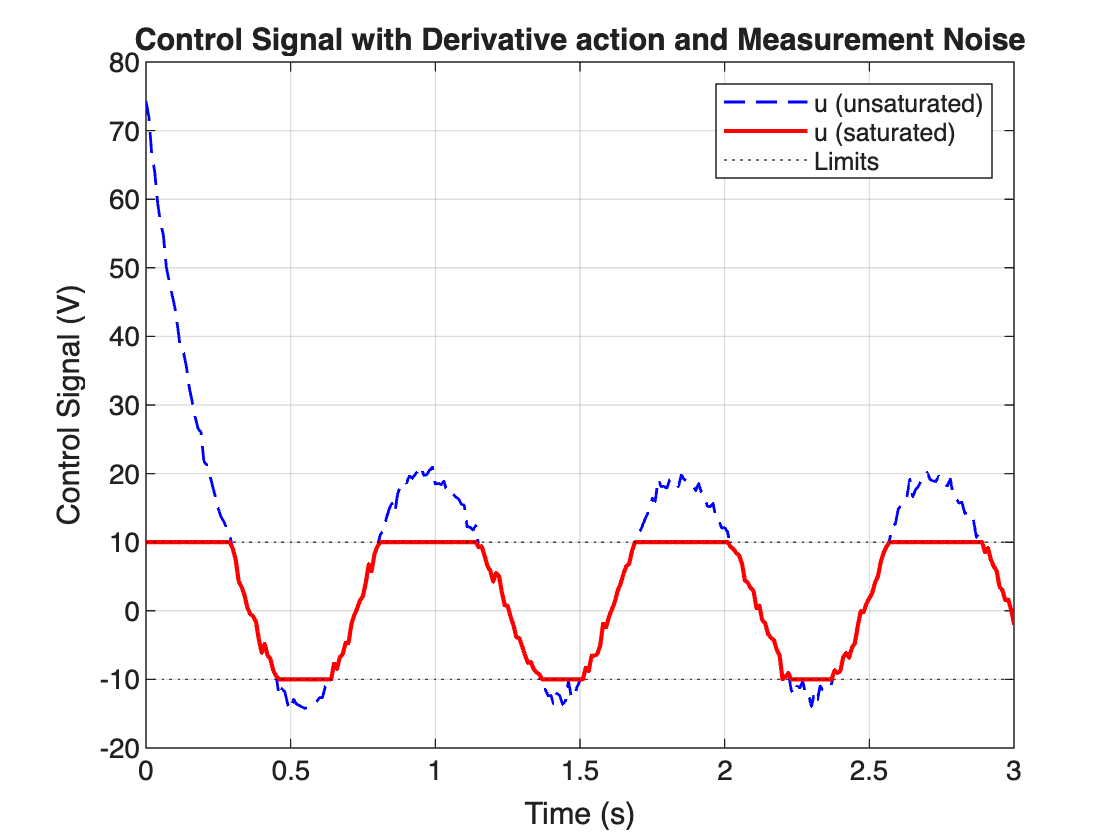

% Control Signals
figure;
plot(t, u, 'b--', 'LineWidth', 1);
hold on;
plot(t, u_sat, 'r', 'LineWidth', 1.5);
yline(10,'k:'), yline(-10,'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal with Derivative action and Measurement Noise');
legend('u (unsaturated)','u (saturated)','Limits');
xlim([0 3]); 

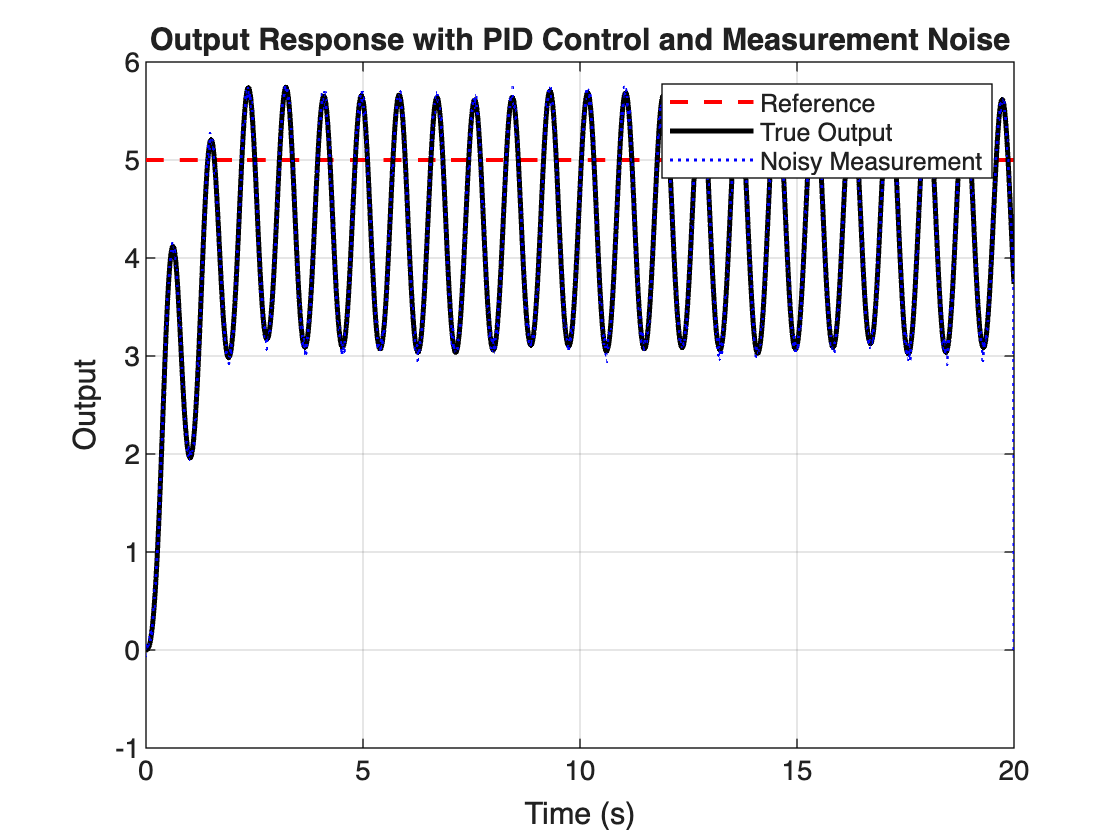


% Output Response
figure;
plot(t, r, 'r--', 'LineWidth', 1.5); hold on;
plot(t, y, 'k', 'LineWidth', 1.8);
plot(t, y_noisy, 'b:', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response with PID Control and Measurement Noise');
legend('Reference','True Output','Noisy Measurement');

With Low-pass Filtering-

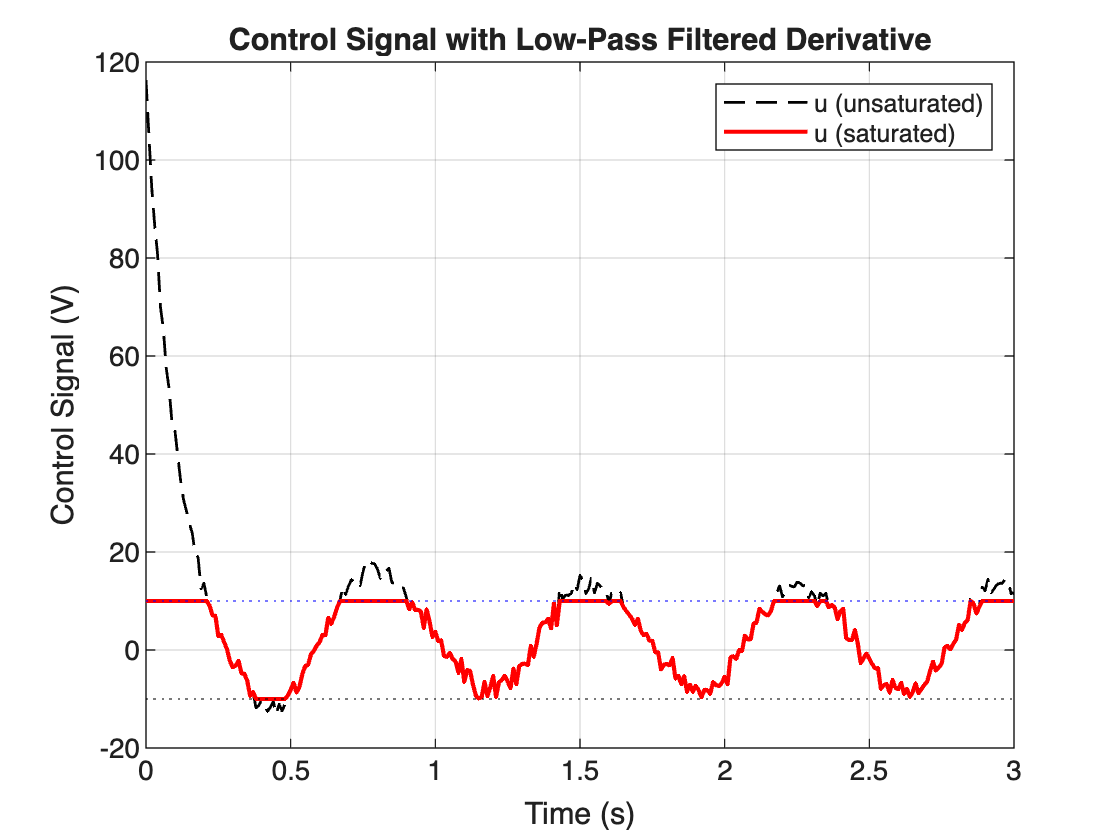


Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);


tau = 0.1;
alpha = tau / (tau + dt);

% Initialization
y1 = zeros(1,N);
y1_dot = 0; y1_ddot = 0;
y1_noisy = zeros(1,N);

u1_unsat = zeros(1,N);
u1_sat = zeros(1,N);

int_e1 = 0;
e_filt = 0;
e_filt_prev = 0;

for k = 1:N-1

    % Noisy measurement
    y1_noisy(k) = y1(k) + 0.05*randn;

    % Error
    e1 = r(k) - y1_noisy(k);

    % Low-pass filtered error
    e_filt = alpha*e_filt + (1-alpha)*e1;

    % Derivative action from filtered error
    u1_d = Kd * (e_filt - e_filt_prev)/dt;

    % Unsaturated PID control
    u1_unsat(k) = Kp*e1 + Ki*int_e1 + u1_d;

    % Saturation
    u1_sat(k) = max(min(u1_unsat(k),10),-10);

    % Anti-windup integrator
    int_e1 = int_e1 + (e1 + (u1_sat(k)-u1_unsat(k))/Kt)*dt;

    % Plant dynamics
    y1_tdot = 50*u1_sat(k) - 20*y1(k) - 25*y1_dot - 8*y1_ddot;
    y1_ddot = y1_ddot + y1_tdot*dt;
    y1_dot  = y1_dot  + y1_ddot*dt;
    y1(k+1) = y1(k)   + y1_dot*dt;

    % Store previous filtered error
    e_filt_prev = e_filt;
end

% Control Signal
figure;
plot(t, u1_unsat, 'k--', 'LineWidth', 1);
hold on;
plot(t, u1_sat, 'r', 'Linewidth', 1.5);
yline(10, 'b:'), yline(-10, 'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal with Low-Pass Filtered Derivative');
legend('u (unsaturated)','u (saturated)');
xlim([0 3])

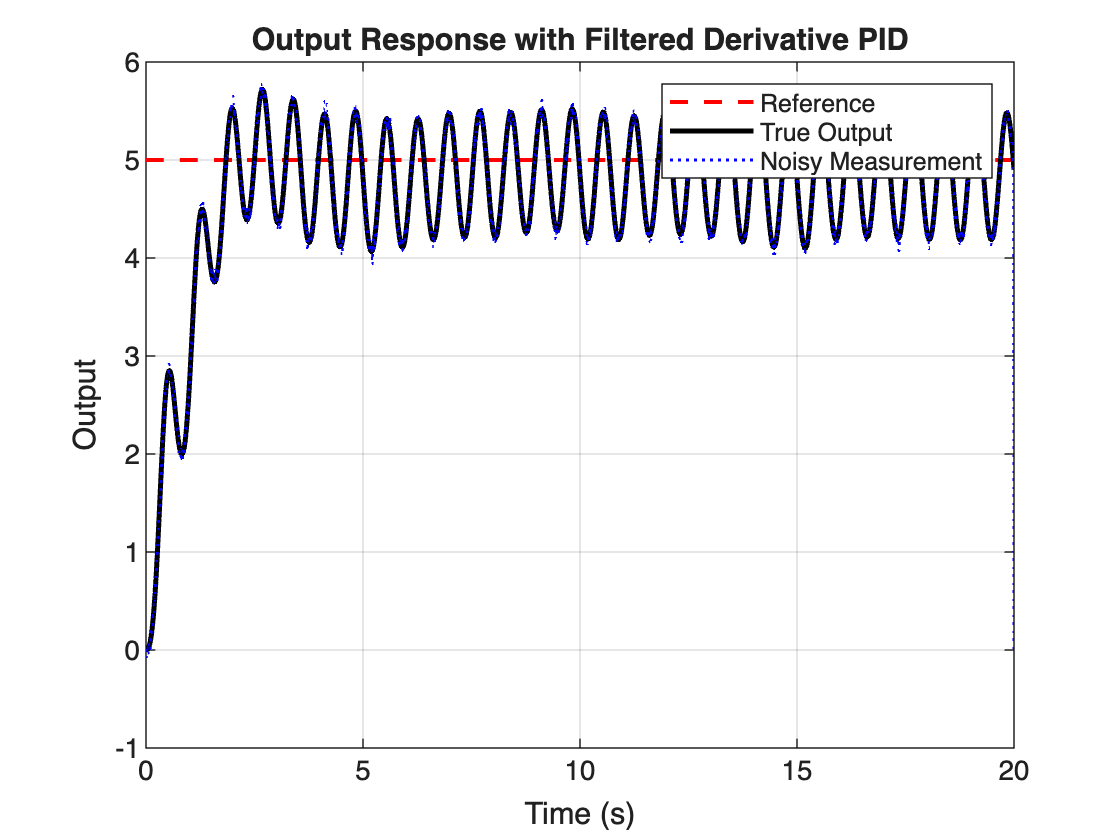


% Output Response
figure;
plot(t, r, 'r--', 'LineWidth', 1.5); hold on;
plot(t, y1, 'k', 'LineWidth', 1.8);
plot(t, y1_noisy, 'b:', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response with Filtered Derivative PID');
legend('Reference','True Output','Noisy Measurement');

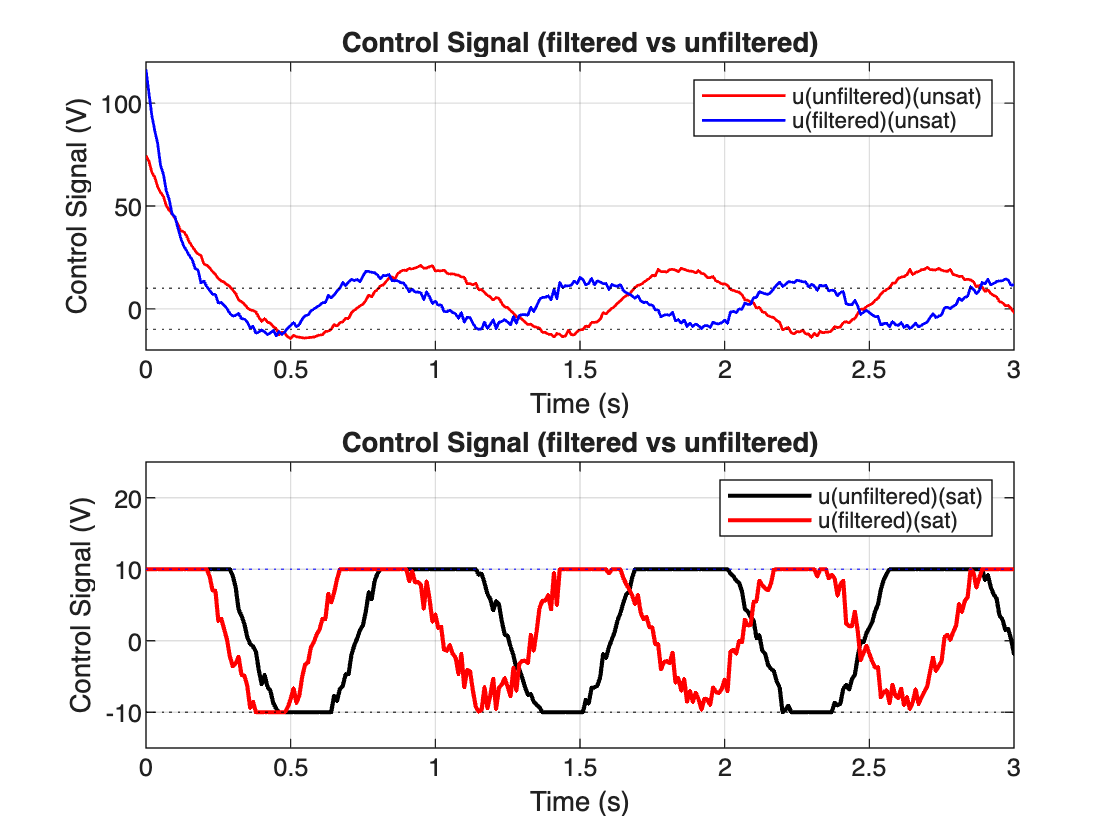


%Comapre plots

figure;
subplot(2,1,1)
plot(t, u, 'r', 'LineWidth', 1);
hold on;
plot(t, u1_unsat, 'b', 'LineWidth', 1);
yline(10, 'k:'), yline(-10, 'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal (filtered vs unfiltered)');
legend('u(unfiltered)(unsat)','u(filtered)(unsat)');
xlim([0 3])
ylim([-20 120])

subplot(2,1,2)
plot(t, u_sat, 'k', 'Linewidth', 1.5);
hold on;
plot(t, u1_sat, 'r', 'Linewidth', 1.5);
yline(10, 'b:'), yline(-10, 'k:');
grid on;
xlabel('Time (s)');
ylabel('Control Signal (V)');
title('Control Signal (filtered vs unfiltered)');
legend('u(unfiltered)(sat)','u(filtered)(sat)');
xlim([0 3])
ylim([-15 25]) 

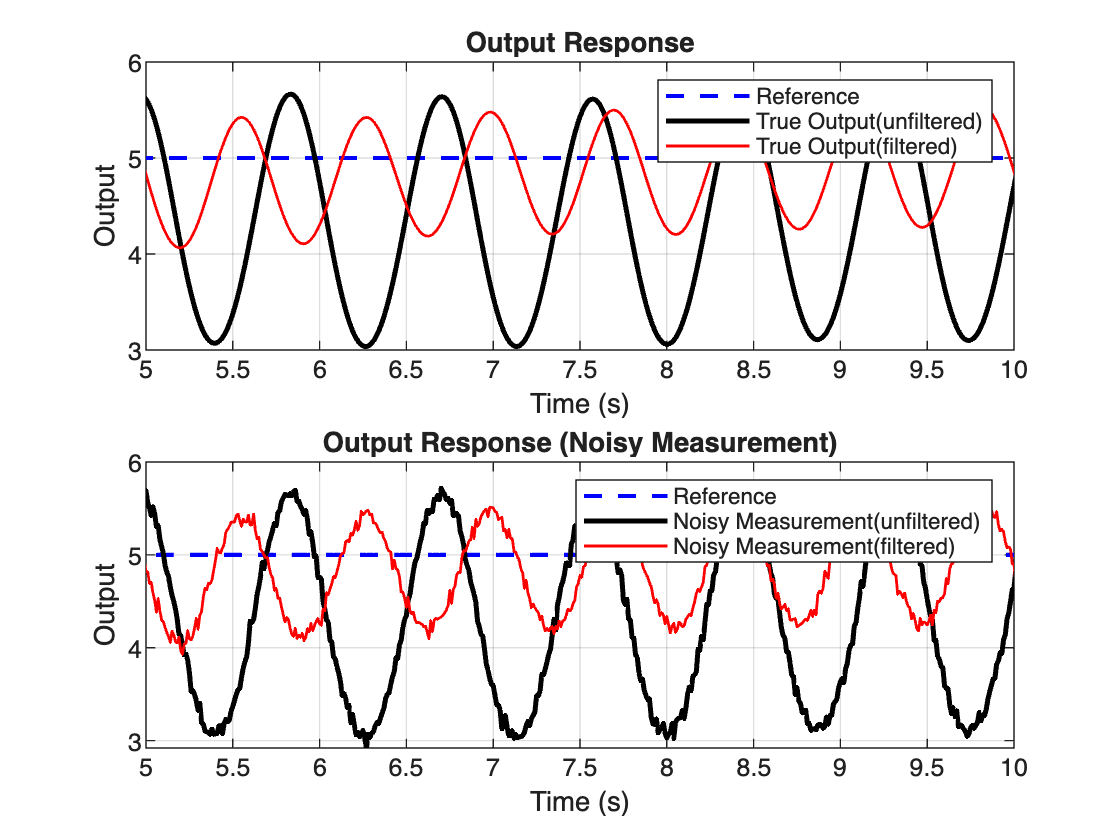

% Output Response
figure;
subplot(2,1,1)
plot(t, r, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, y, 'k', 'LineWidth', 1.8);
plot(t, y1, 'r', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response');
legend('Reference','True Output(unfiltered)','True Output(filtered)');
xlim([5 10])

subplot(2,1,2)
plot(t, r, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, y_noisy, 'k', 'LineWidth', 1.8);
plot(t, y1_noisy, 'r', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Output Response (Noisy Measurement)');
legend('Reference','Noisy Measurement(unfiltered)','Noisy Measurement(filtered)');
xlim([5 10])


% Ignore first few seconds to incorporate only steady-state noise
t_start = 5;
idx = find(t >= t_start);

% Standard deviation of control signals
std_unfiltered = std(u(idx));
std_filtered   = std(u1_unsat(idx));

fprintf('Std (Unfiltered Derivative) = %.3f V\n', std_unfiltered);

Std (Unfiltered Derivative) = 11.241 V



fprintf('Std (Filtered Derivative)   = %.3f V\n', std_filtered);

Std (Filtered Derivative)   = 7.504 V


Derivative action amplifies high-frequency noise when the measured output contains noise. This leads to large, rapid oscillations in the control signal. By applying a low-pass filter before differentiation, high-frequency noise is attenuated. This reduces noise amplification while preserving the damping effect of the derivative term, resulting in a smoother control signal and improved system behavior.

## Trajectory Tracking



% PID Controller Gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);

% Simulation parameters
dt = 0.01;
t  = 0:dt:20;
N  = length(t);

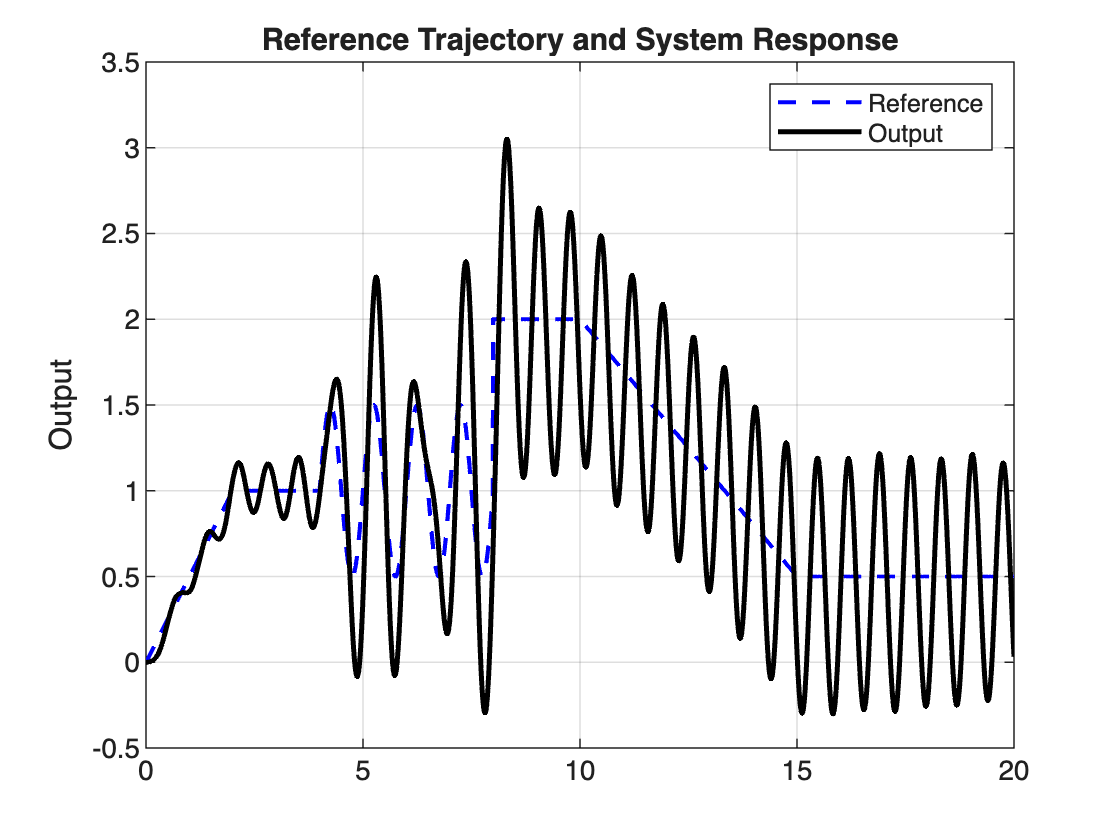

% Reference 
r = zeros(1,N);
for k = 1:N
    if t(k) < 2
        r(k) = 0.5*t(k);                          % ramp up
    elseif t(k) < 4
        r(k) = 1;                                % hold
    elseif t(k) < 8
        r(k) = 1 + 0.5*sin(2*pi*(t(k)-4));       % oscillation
    elseif t(k) < 10
        r(k) = 2;                                % step up
    elseif t(k) < 15
        r(k) = 2 - 0.3*(t(k)-10);                % ramp down
    else
        r(k) = 0.5;                              % final hold
    end
end

tau = 0.1;
alpha = tau / (tau + dt);

% Initialization
y = zeros(1,N);
y_dot = 0; y_ddot = 0;
y_noisy = zeros(1,N);

u = zeros(1,N);
u_sat = zeros(1,N);

int_e = 0;
e_filt = 0;
e_filt_prev = 0;

for k = 1:N-1

    % Noisy measurement
    y_noisy(k) = y(k) + 0.05*randn;

    % Error
    e = r(k) - y_noisy(k);

    % Low-pass filtered error
    e_filt = alpha * e_filt + (1-alpha)*e;

    % Derivative action from filtered error
    u_d = Kd * (e_filt - e_filt_prev)/dt;

    % Unsaturated PID control
    u(k) = Kp*e + Ki*int_e + u_d;

    % Saturation
    u_sat(k) = max(min(u(k),10),-10);

    % Tracking error
    tracking_error = r - y;

    % Anti-windup integrator
    int_e = int_e + (e + (u_sat(k)-u(k))/Kt)*dt;

    % Plant dynamics
    y_tdot = 50*u_sat(k) - 20*y(k) - 25*y_dot - 8*y_ddot;
    y_ddot = y_ddot + y_tdot*dt;
    y_dot  = y_dot  + y_ddot*dt;
    y(k+1) = y(k)   + y_dot*dt;

    % Store previous filtered error
    e_filt_prev = e_filt;
end

% Reference & Output
figure;
plot(t, r, 'b--', 'LineWidth', 1.5); hold on;
plot(t, y, 'k', 'LineWidth', 1.8);
grid on;
ylabel('Output');
title('Reference Trajectory and System Response');
legend('Reference','Output');

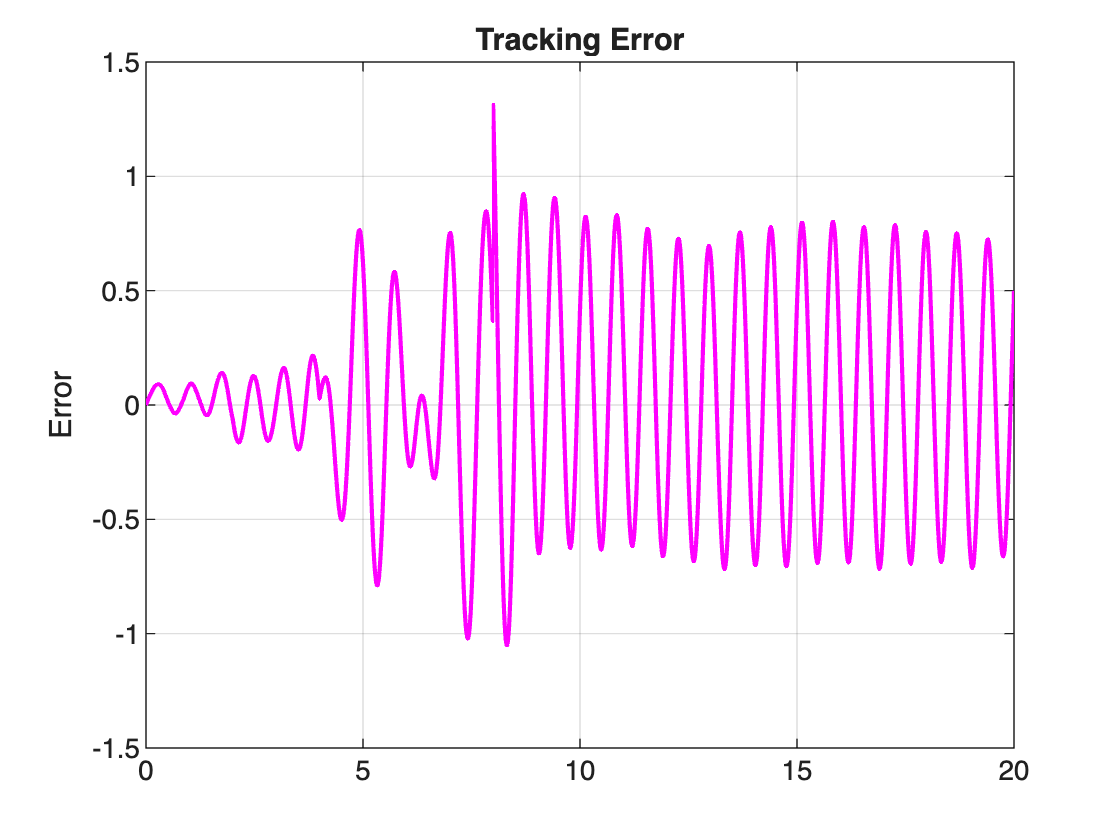


% Tracking Error
figure;
plot(t, tracking_error, 'm', 'LineWidth', 1.5);
grid on;
ylabel('Error');
title('Tracking Error');

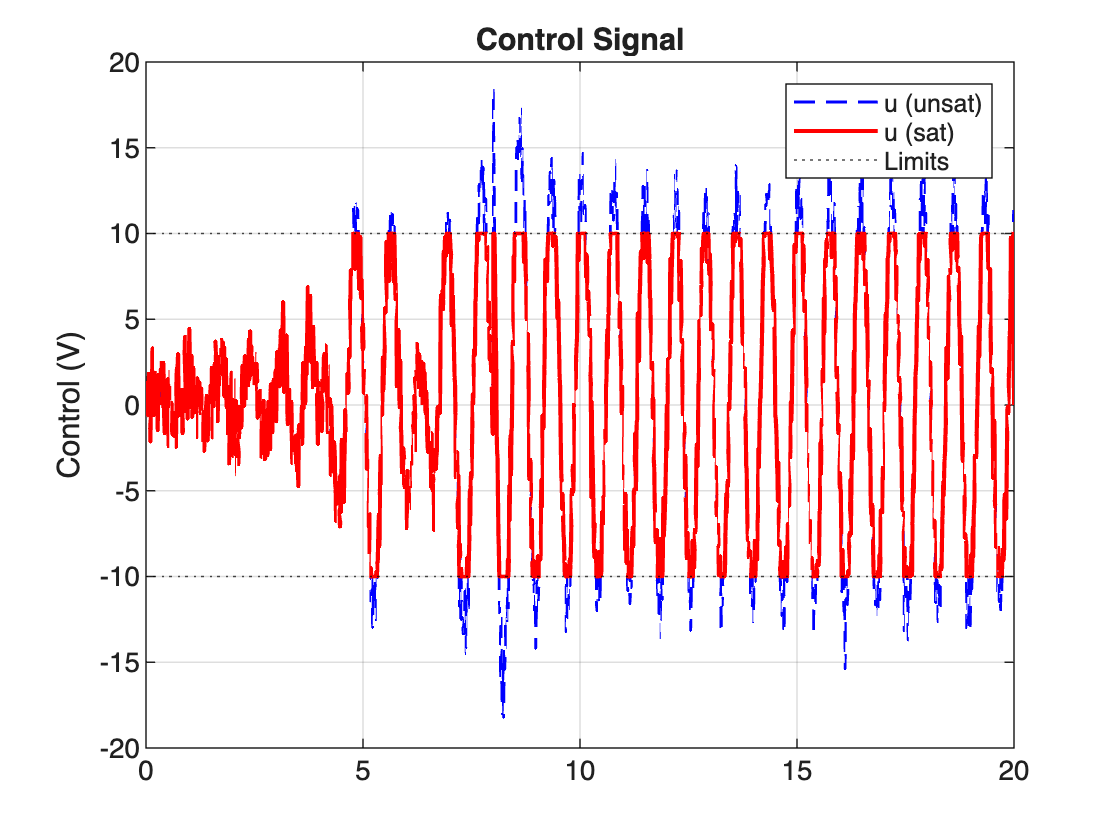


% Control Signal
figure;
plot(t, u, 'b--', 'LineWidth', 1); hold on;
plot(t, u_sat, 'r', 'LineWidth', 1.5);
yline(10,'k:'), yline(-10,'k:');
grid on;
ylabel('Control (V)');
title('Control Signal');
legend('u (unsat)','u (sat)','Limits');

Calculate RMS tracking error:   $e_{\textrm{RMS}} =\sqrt{\frac{1}{N}\sum_{i=1}^N e_i^2 }$

rms_error = sqrt(mean(tracking_error.^2));
fprintf ('RMS Error : %.4f\n', rms_error );

RMS Error : 0.4681


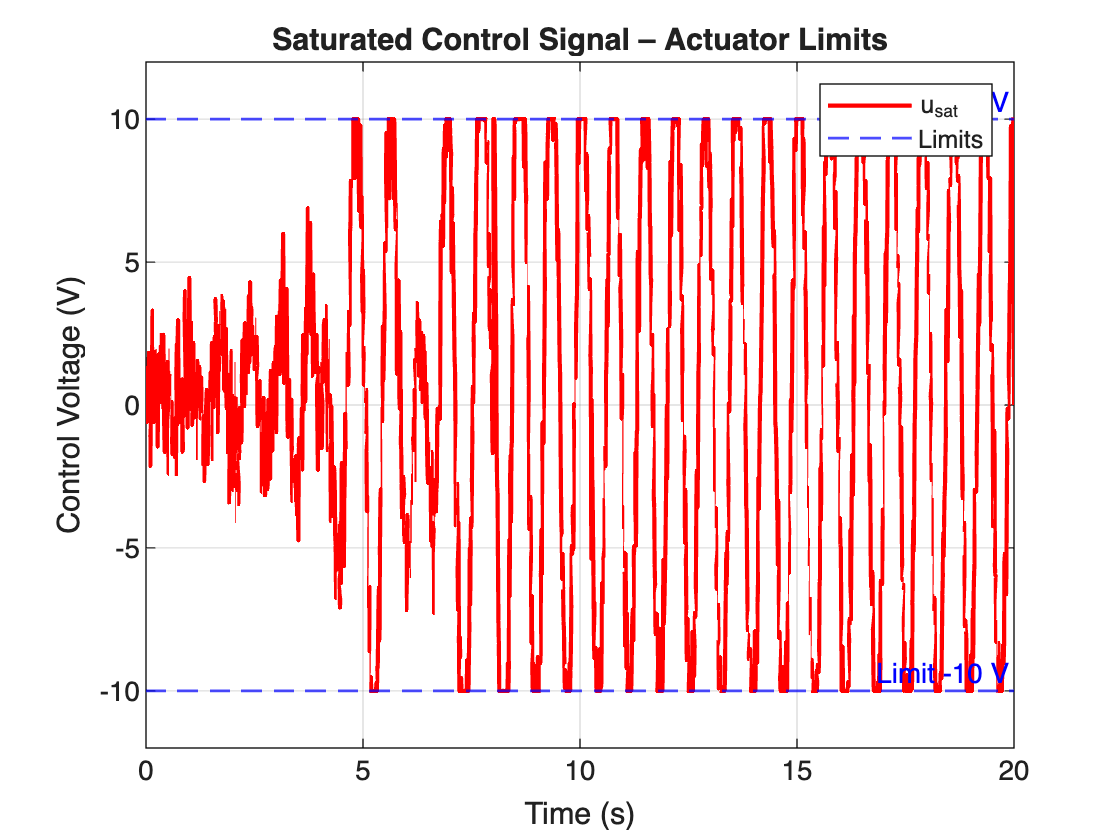

% Showing using saturated control signal plot
figure;
plot(t, u_sat, 'r', 'LineWidth', 1.5); hold on;
yline(10,'b--','Limit +10 V','LineWidth',1);
yline(-10,'b--','Limit -10 V','LineWidth',1);
grid on;
xlabel('Time (s)');
ylabel('Control Voltage (V)');
title('Saturated Control Signal – Actuator Limits');
legend('u_{sat}','Limits');
ylim([-12 12])